%Part a
v = 1:1000 % vector

v =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


b = length(v)

b = 1000

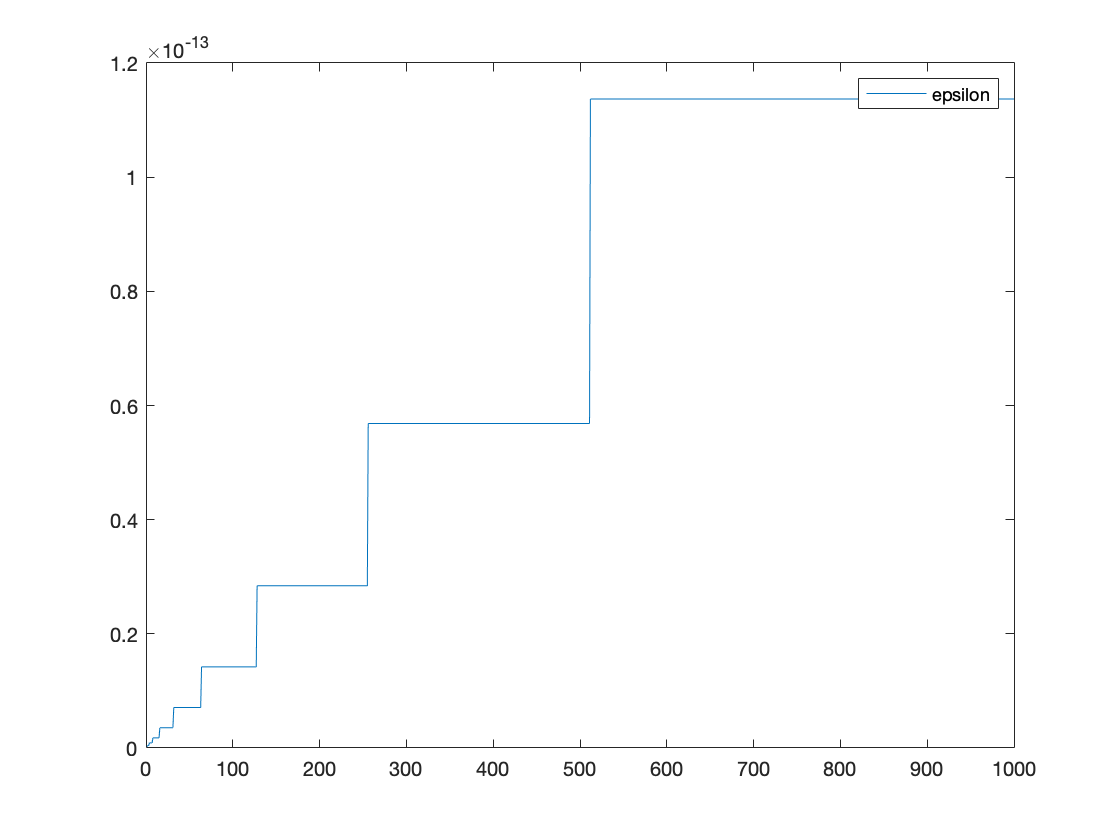

B = 1;
for i=1:b
    B(i)=  eps(i);
end
plot(v,B)
legend('epsilon');


eps(43)

ans = 7.1054e-15

ep(43)

ans = 7.1054e-15


%from the plot we realize as M is increasing the epsilon is increasing.the
%reason why epsilon is constant(same for some m values) is  sometimes  that for cases 2^x and 2^x+1
%where x is an odd number then the epsilon remains constant.


%Part c

Q = 1:1000 % vector

Q =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


b = length(Q)

b = 1000

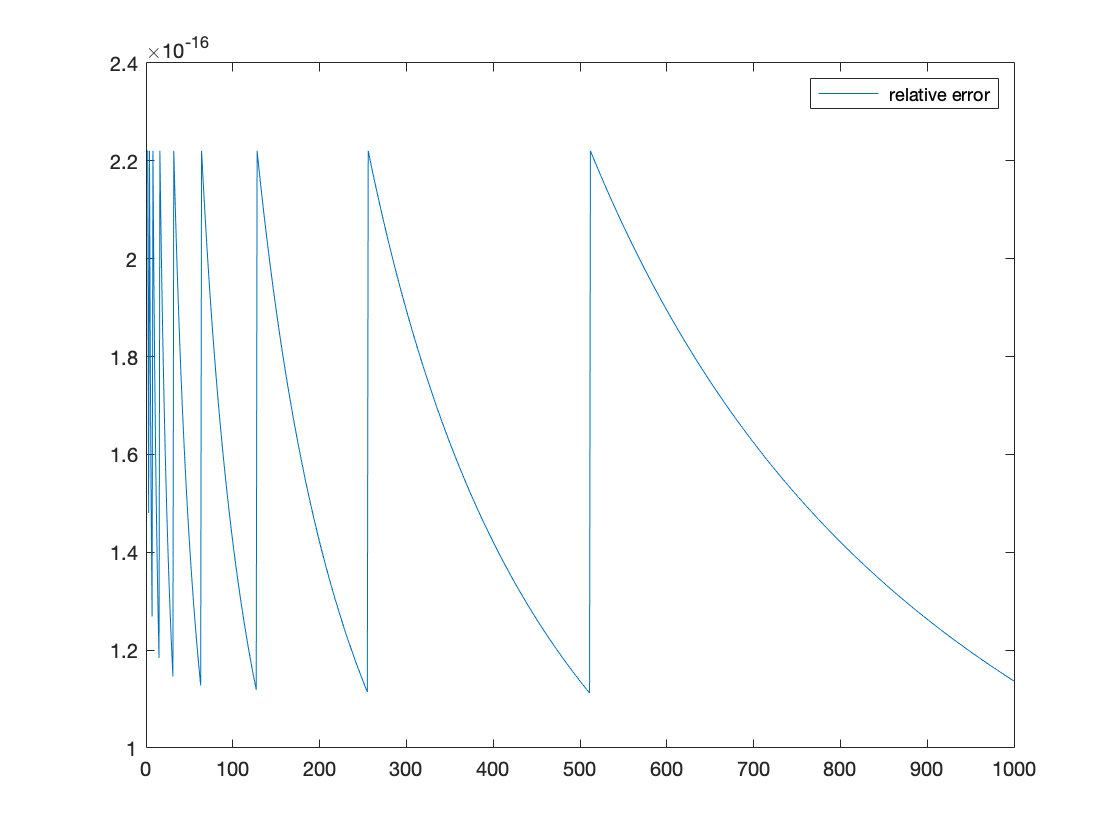

B = 1;
vec=[];
for i=1:b
    B(i)=  eps(i)/i;
P=max(B);
end
plot(Q,B)
legend(' relative error');

upperbound = P

upperbound = 2.2204e-16


%for this question we learn that from question a there were some numbers
%with similar epsilon thus we can group these numbers in groups like group
%a1, b1, c1 etc i.e a group of numbers with similar epsilon numbers . Now
%for every group let say a1 it has numbers from 1 to 16 , thus since their
%epsilon is the same if we find the relative error , 1 will have the
%largest relative error while 16 will have the lowest relative error
%because it has a bigger denominator.

%part d

eps("single")

ans = single
1.1921e-07

%1=1.0000......0*2^0
%the next number is 1.0000........1*2^0
%the difference is epsolon =2^-23
k = 2^-23

k = 1.1921e-07

%part b

V = 1:1000 % vector

V =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


a = length(V)

a = 1000

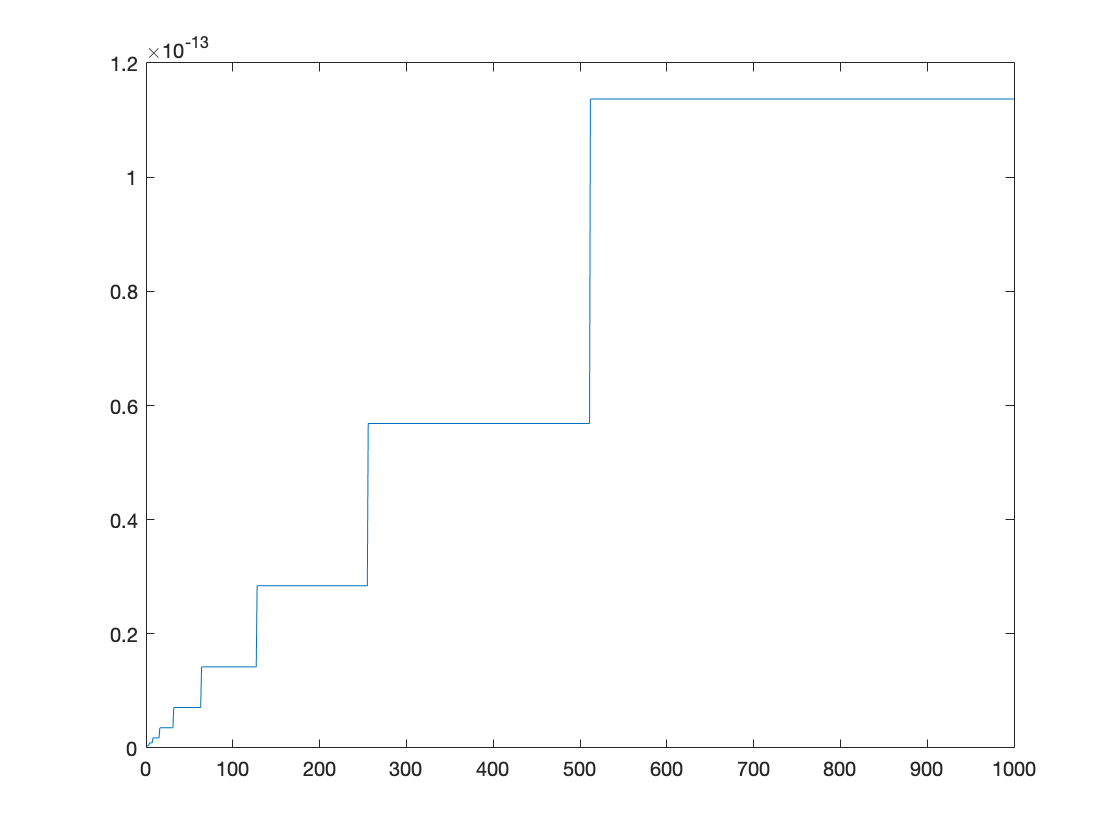


for i=1:a
    M(i)=  ep(i);
end
plot(V,M)

ep(10)

ans = 1.7764e-15

eps(10)

ans = 1.7764e-15

%the graph we obtained here is similar to the one we obtained in part a .
%Thus similar explanation.

function eplison = ep(m)
 % your code goes here
 eplison = 2^round(log(m));
 count = 1;
while(m+eplison)> m
 eplison=eplison/2;
 count = count + 1;
 end
 eplison = 2 * eplison ;
 count;
 m;
end